# EFA analysis of PheH SEC data

**The data and analysis were published in:**

Meisburger SP, Taylor AB, Khan CA, Zhang S, Fitzpatrick PF, Ando N. *Domain movements upon activation of phenylalanine hydroxylase characterized by crystallography and chromatography-coupled small-angle X-ray scattering.* JACS 138(20): 6506?16 (2016). [http://dx.doi.org/10.1021/jacs.6b01563](http://dx.doi.org/10.1021/jacs.6b01563)

Code by:

- Steve Meisburger

- May 20, 2020

addpath('../matlab/'); % add code to path

## load data

load data/PheH_0phe_SEC.mat q I sigma name
fprintf(1,'loaded dataset: %s\n',name);

loaded dataset: G1_11_03_14/PHEH_SEC/PheHc_SEC_run2


## Create EFA object

E = EFA(I,sigma,'svd_mode','fast');

## Calculate evolving factors

sr = E.evolvingFactors(7,'reverse',3);
sf = E.evolvingFactors(7,'forward',3);

## Automatically determine inflection points

[xr] = E.fitInflection(sr,'reverse',1.1,30);
[xf] = E.fitInflection(sf,'forward',1.1,30);

% put in first-in, first-out order
xf = sort(xf,'ascend');
xr = sort(xr,'ascend');

% get rid of extra components (those with no inflection)
isIncl = ~isnan(xf) & ~isnan(xr);
xf = xf(isIncl);
xr = xr(isIncl);

ncomp = numel(xf); % number of components

disp(table(xf,xr,'VariableNames',{'Start','Stop'}))

    Start      Stop 
    ______    ______

    143.49    194.82
       162    353.59
    317.63    375.88



## Plot results

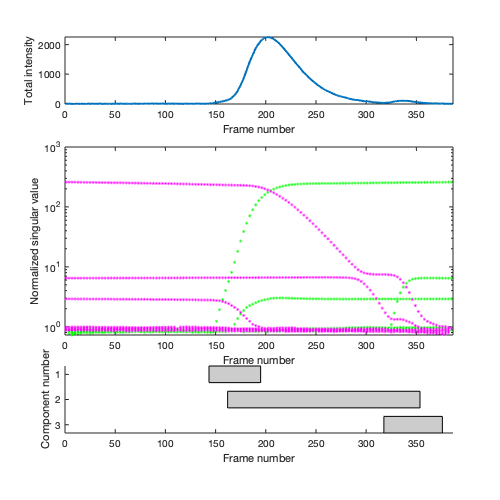

fh = figure;fh.Position(3:4) = [500,500];
xrange = [0,E.Nc+.5];

subplot(4,1,1);plot(sum(E.I,1)','-','LineWidth',2)
set(gca,'XLim',xrange);
ylabel('Total intensity');xlabel('Frame number');

subplot(4,1,2:3);semilogy(sf','g.');hold on;plot(sr','m.');
set(gca,'XLim',xrange);
ylabel('Normalized singular value');xlabel('Frame number');

subplot(4,1,4);
for j=1:ncomp
    patch('XData',[0,1,1,0]*(xr(j)-xf(j)) + xf(j),...
        'YData',[-1,-1,1,1]*.33 + j,...
        'FaceColor',[1,1,1]*.8);hold on;
end
axis ij
set(gca,'XLim',xrange,'Ylim',[-Inf,Inf]);

ylabel('Component number');xlabel('Frame number');

## quick basis rotation

[y,c,R] = E.quickRotate(xf,xr);

disp(R)

   -2.4854  -20.4261   -0.1088
    0.2665    0.3145  -10.2754
    7.5185   -0.6393    0.2956



## plot results

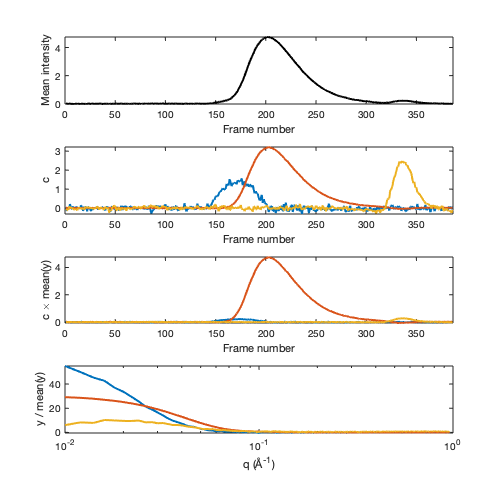

fh = figure;fh.Position(3:4) = [500,500];
xrange = [0,E.Nc+.5];

total_intensity = mean(y,1);

subplot(4,1,1);plot(mean(E.I,1)','k-','LineWidth',2)
set(gca,'XLim',xrange);
ylabel('Mean intensity');xlabel('Frame number');

subplot(4,1,2);plot(c','-','LineWidth',2)
set(gca,'XLim',xrange);
ylabel('c');xlabel('Frame number');

subplot(4,1,3);plot(c'.*total_intensity,'-','LineWidth',2)
set(gca,'XLim',xrange);
ylabel('c \times mean(y)');xlabel('Frame number');

subplot(4,1,4);semilogx(q, y./total_intensity,'-','LineWidth',2)
xlabel('q (Å^{-1})');
ylabel('y / mean(y)');

## Refine using ALS, inspect chi-squared

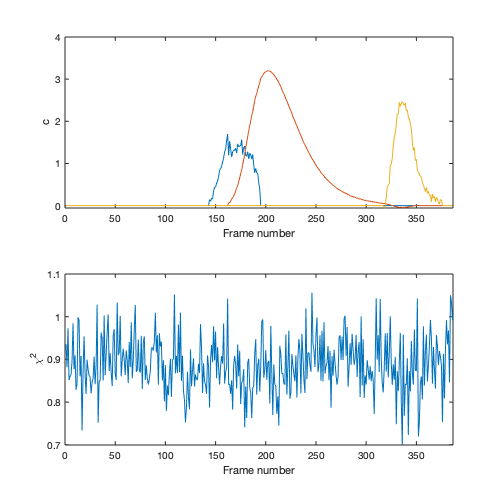

x = 1:size(I,2);

% set up components for ALS
C = arrayfun(@(xmin,xmax) Component(... 
    Concentration(x,'simple','xmin',xmin,'xmax',xmax),Profile(q,'simple')),...
    xf,xr);

% initialize Mixture with result from quickRotate
M = Mixture(C);
M.uProfile = arrayfun(@(n) y(:,n),(1:numel(xf))','Uni',0);
R = REGALS(I,sigma);
M = R.fitConcentrations(M);

% look at residual
resid = (I - M.Ireg)./sigma;

% plot the results
fh = figure;fh.Position(3:4) = [500,500];
xrange = [0,E.Nc+.5];
subplot(2,1,1);plot(M.concentrations,'-','LineWidth',1)
set(gca,'XLim',xrange);
ylabel('c');xlabel('Frame number');

subplot(2,1,2);plot(mean(resid.^2,1),'-','LineWidth',1)
set(gca,'XLim',xrange);
ylabel('\chi^2');xlabel('Frame number');

Looks OK to me.

## Run several iterations of ALS to fully converge result

% set stopFun to return true when 50 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  50,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run for 50 iterations
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 0.887918, delta_profile = [15.3 593 220]
 2, x2 = 0.887834, delta_profile = [0.863 0.00905 3.7]
 3, x2 = 0.887774, delta_profile = [0.622 0.00232 3.5]
 4, x2 = 0.887725, delta_profile = [0.477 0.00295 3.31]
 5, x2 = 0.887683, delta_profile = [0.373 0.00251 3.14]
 6, x2 = 0.887646, delta_profile = [0.294 0.00199 2.98]
 7, x2 = 0.887612, delta_profile = [0.234 0.00156 2.83]
 8, x2 = 0.887581, delta_profile = [0.187 0.00123 2.69]
 9, x2 = 0.887552, delta_profile = [0.15 0.000978 2.56]
10, x2 = 0.887525, delta_profile = [0.12 0.00078 2.43]
11, x2 = 0.887499, delta_profile = [0.0971 0.000624 2.32]
12, x2 = 0.887475, delta_profile = [0.0784 0.000502 2.22]
13, x2 = 0.887452, delta_profile = [0.0634 0.000405 2.12]
14, x2 = 0.887431, delta_profile = [0.0514 0.000328 2.02]
15, x2 = 0.887410, delta_profile = [0.0417 0.000266 1.93]
16, x2 = 0.887390, delta_profile = [0.0338 0.000216 1.85]
17, x2 = 0.887371, delta_profile = [0.0275 0.000177 1.77]
18, x2 = 0.887353, delta_profile = [0.0223 

## plot the end results

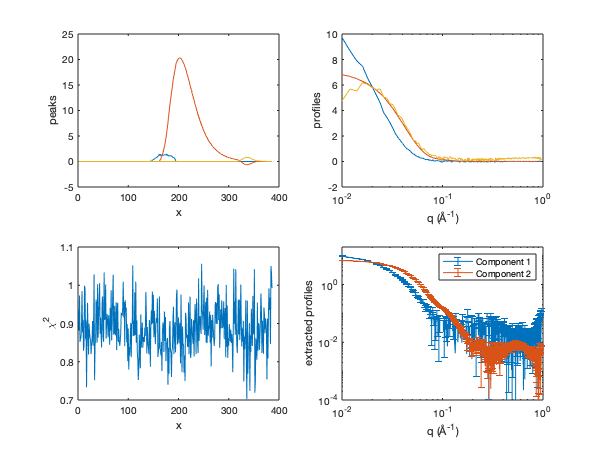

% extract the two particle components (no regularization)
[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);

fh = figure;fh.Position(3:4) = [600,450];
subplot(2,2,1);plot(M1.concentrations);xlabel('x');ylabel('peaks');
subplot(2,2,3);plot(mean(resid.^2,1));xlabel('x');ylabel('\chi^2');
subplot(2,2,2);semilogx(q,M1.profiles);xlabel('q (Å^{-1})');ylabel('profiles');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','Component 1');hold on;
errorbar(q,I2,sigma2,'DisplayName','Component 2');
set(gca,'XScale','Log','Yscale','Log','Ylim',[1E-4,2E1]);
legend show; xlabel('q (Å^{-1})'); ylabel('extracted profiles');